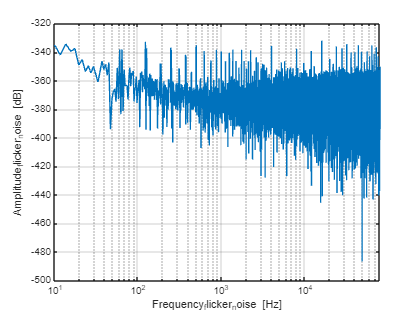

close all;
v1 =  out.m(:,2);
%v2 =  out.x_without_flicker(:,2);
v1=v1-0.9; % Remove the DC component from digital signal.
%v2 = v2 - 0.9;
OSR = 1024; % Over-sampling Ratio
Fs = 2e3*OSR;
NFFTv = 32768*32;

len1 = length(v1);
v1 = v1(len1-NFFTv+1:end); % Take last NFFTv samples of v1
L1 = length(v1);

len2 = length(v2);
v2 = v2(len2-NFFTv+1:end); % Take last NFFTv samples of v1
L2 = length(v2);

fv = Fs / 2 * linspace(0, 1, NFFTv / 2 + 1); % Frequency vector (Hz)
FS = 1.8;

% Compute PSD & plot
% Use this for no LEAKAGE :)

wind1 = hann(L1, 'periodic');
wind2 = hann(L2, 'periodic');
fft_outv1 = fft(v1 .* wind1, NFFTv);
fft_outv2 = fft(v2 .* wind2, NFFTv);
% Ptot = (abs(fft_outv)).^2; % Power spectrum of the signal
    
% Normalise the peak of signal

Ptot1 = (abs(fft_outv1)/(FS * sum(wind1) * 1/4)).^2; % Power spectrum of the signal
fft_onesided1 = abs(Ptot1(1:NFFTv/2+1));
figure;
semilogx(fv, 10*log10(fft_onesided1)); 
xlim([10, 80e3])
xlabel('Frequency_flicker_noise [Hz]');
ylabel('Amplitude_flicker_noise [dB]');
grid on;

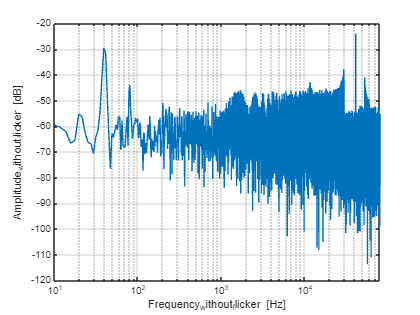


% SNDR calculation
% Select appropriate signal bin for SNDR calculation
fin = (3117/(2*(pi))); 
k = round(fin * NFFTv / Fs) + 1;
sigbin = k-1:k+1;
% For signal power, integrate over input signal BW
sigpow1 = sum(fft_onesided1(sigbin));
% For noise Power, integrate till nyquist frequency and subtract signal
% power.
npow1 = sum(fft_onesided1(3:round(end/OSR))) - sigpow1;

sndr1 = 10*log10(sigpow1./npow1); % Compute SNDR

% Normalise the peak of signal

Ptot2 = (abs(fft_outv2)/(FS * sum(wind2) * 1/4)).^2; % Power spectrum of the signal
fft_onesided2 = abs(Ptot2(1:NFFTv/2+1));
figure;
semilogx(fv, 10*log10(fft_onesided2)); 
xlim([10, 80e3])
xlabel('Frequency_without_flicker [Hz]');
ylabel('Amplitude_without_flicker [dB]');
grid on;

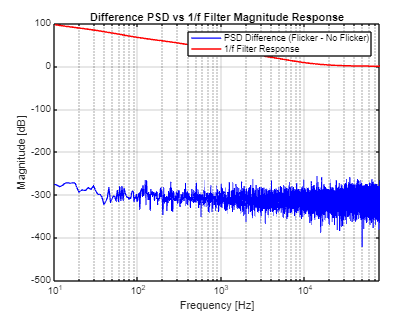


% SNDR calculation
% Select appropriate signal bin for SNDR calculation
%fin = (3117/(2*(pi))); 
%k = round(fin * NFFTv / Fs) + 1;
%sigbin = k-1:k+1;
% For signal power, integrate over input signal BW
sigpow2 = sum(fft_onesided2(sigbin));
% For noise Power, integrate till nyquist frequency and subtract signal
% power.
npow2 = sum(fft_onesided2(3:round(end/OSR))) - sigpow2;

sndr2 = 10*log10(sigpow2./npow2); % Compute SNDR

% ---- Difference Plot Between PSDs ----

% ---- Difference Plot Between PSDs ----
psd1_dB = 10*log10(fft_onesided1);
psd2_dB = 10*log10(fft_onesided2);
diffPSD = psd1_dB - psd2_dB;   % Difference in dB

figure;
% START PLOTTING FROM INDEX 2 (to skip 0 Hz)
% Index 2 corresponds to the first frequency bin > 0
semilogx(fv(2:end), diffPSD(2:end), 'b', 'LineWidth', 1.2);

hold on; grid on;

% Ensure 'f' and 'mag_dB' exist from your previous filter design steps
% Check if f also starts at 0. If so, use f(2:end) and mag_dB(2:end)
if exist('f', 'var') && exist('mag_dB', 'var')
    semilogx(f, 3*mag_dB, 'r', 'LineWidth', 1.5); % Why 3*? Ensure this scaling is intended.
    legend('PSD Difference (Flicker - No Flicker)', '1/f Filter Response');
else
    legend('PSD Difference (Flicker - No Flicker)');
    warning('Variables f and mag_dB not found in workspace.');
end

xlim([10, 80e3]);
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
title('Difference PSD vs 1/f Filter Magnitude Response');